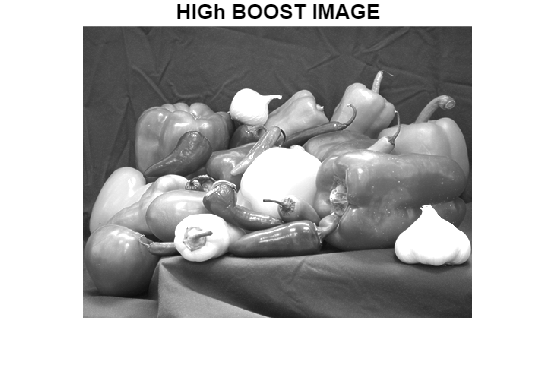

img = imread('peppers.png');
grayImg = rgb2gray(img);
noisyImg = imnoise(grayImg, 'salt & pepper', 0.05);

h = fspecial('average', [3 3]);
avgFilter = imfilter(noisyImg, h);

g = fspecial('gaussian', [3 3], 0.5);
gaussFilter = imfilter(noisyImg, g);

medFilter = medfilt2(noisyImg, [3 3]);

l4 = [0 -1 0; -1 4 -1; 0 -1 0];
lap4 = imfilter(double(grayImg), l4, 'replicate');
lapAdded = imadd(lap4, double(grayImg));
lapAdded = uint8(lapAdded);

buildin = fspecial('laplacian', 0.2);
lapBuilt = imfilter(grayImg, buildin, 'replicate');

blurred=imgaussfilt(grayImg,1);

unsharpImg=imsubtract(grayImg,blurred);
sharpenedImg=imadd(grayImg,unsharpImg);

A=1.5;
highboostImg=(A-1)* grayImg + sharpenedImg;
imshow(highboostImg);
title("HIGh BOOST IMAGE");

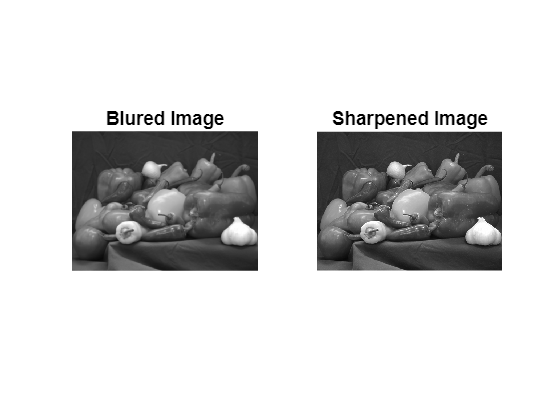



figure;
subplot(1,2,1); imshow(blurred);title("Blured Image");
subplot(1,2,2); imshow(sharpenedImg);title("Sharpened Image");

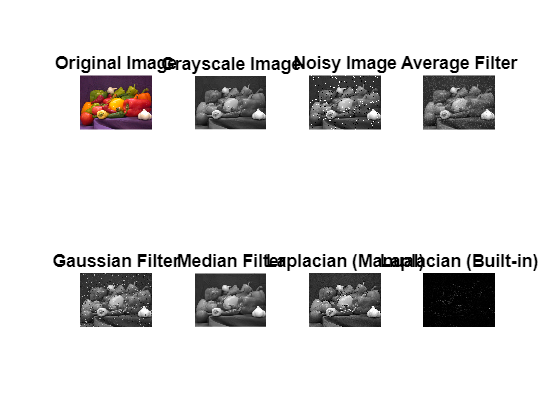


figure;
subplot(2,4,1); imshow(img); title('Original Image');
subplot(2,4,2); imshow(grayImg); title('Grayscale Image');
subplot(2,4,3); imshow(noisyImg); title('Noisy Image');
subplot(2,4,4); imshow(avgFilter); title('Average Filter');
subplot(2,4,5); imshow(gaussFilter); title('Gaussian Filter');
subplot(2,4,6); imshow(medFilter); title('Median Filter');
subplot(2,4,7); imshow(lapAdded, []); title('Laplacian (Manual)');
subplot(2,4,8); imshow(lapBuilt, []); title('Laplacian (Built-in)');